# 1. Building a wing geometry

This function will explain how to build a generic wing geometry using the ALENA software tool. The following topics are discussed:

- Parameterisation methods of a generic lifting surface in ALENA.

- Child geometry object specific to the LiftingSurface class.

## A. Defining a lifting surface

In ALENA a LiftingSurface object can be used to describe any wing-like geometry, for example a wing, vertical stabilizer, canard or strut could be modelled using a LiftingSurface object. In general, a LiftingSurface is required if you want to include aerodynamic forces in your analysis, whereas a Beam object is more suitable for a purely structural analysis.

To create a LiftingSurface object simply define it as a MATLAB variable.

LS = awi.model.LiftingSurface;

When working with LiftingSurface object it is good practice to define the 'SpanVector' property first as this orientates the object in the global coordinate system. Allowable values for the 'SpanVector' are 'Y' and 'Z'. Note that 'X' is not an allowable value as the ALENA aircraft coordinate system has the flow parallel to the global X-axis, therefore in order for the chord direction to be parallel with the flow the span vector cannot be along the global X-axis.

LS.SpanVector = 'Y';

Next, you can begin populating the properties of the LiftingSurface object. 

NOTE - The LiftingSurface class supports multiple parameterisation methods via the 'awi.mixin.Buildable' class, of which LiftingSurface is a subclass, therefore it is not necessary to populate all properties of a LiftingSurface. Instead, only those properties that belong to the chosen parameter set must be defined in order to build the object. As described in "OO_Parametric_object_building_in_ALENA", the available parameter sets can be queried by evaluating the 'ParameterSets' property of object. 

ParamSets = LS.ParameterSets;

For more information on the parameter sets of the LiftingSurface class consult the ALENA documentation. 

**A.1. Defining a lifting surface using the Parametric Set ('pSet')**

In this example we will use the 'pSet' parameter set to build the wing geometry. This set describes a wing using a distribution of sweep, dihedral and angle-of-attack (AoA) angles, as well as the chord distribution and the overall semi-span of the wing.

First, let's try an simple rectangular wing.

LS.Chord     = [4, 4];
LS.Chord_eta = [0, 1];
LS.Span      = 10;

The next step is to define the parameter set that is being used to build the object, which in this case is the 'pSet'. With this defined we can build the obejct and then draw it to check we have actually generated a geometry.

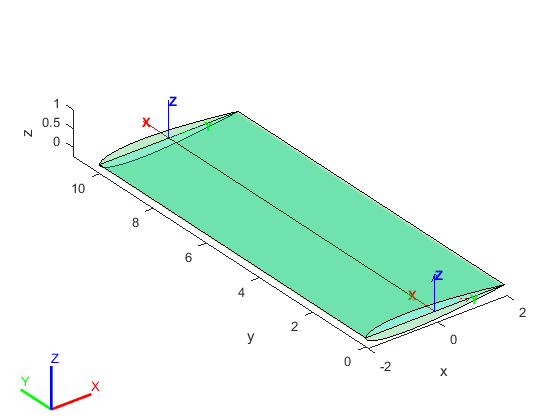

LS.ActiveSet = 'pSet';

build(LS);
draw(LS);

Success! The wing geometry has been defined correctly.

Note that the chord value has two values. This is because we are describing the *distribution* of the chord along the span of the wing instead of the chord at a single point. This vector can be extended to include any number of points so long as the distribution ('Chord_eta') is normalised between zero and one and has the same number of points as 'Chord'. In code this would be written as the condition

assert(numel(LS.Chord) == numel(LS.Chord_eta))

However, this condition only has to be true at the point where the object uses the properties to calculate the geometry, i.e. when the *build* method is executed. Therefore, the user is free to change the chord values and distribution individually so long as at the point of building the number of elements in the vectors are the same. Note - This condition will be checked internally by the object and an error will result if there is a mismatch in array size.

Notice how several graphics have been plotted by a single call to the class *draw* method. 

- The straight black line is the beam axis. This is the beam that will be converted to a set of finite element beam elements when and if this model is converted to a Finite Element Model (FEM). 

- The beam axis has a set of coordinate systems associated with are shown by the red/green/blue axes attached to the beam - these coordinate systems represent the local beam coordinate system that will be used by the relevant beam forumlation in ALENA. 

- The outline of the planform is shown by the pale blue patch. This is the flat plate aerodynamic surface which  will be translated into strips and panels during the FEM conversion process. The calculated LiftingSurface area is the area of this blue patch.

- Finally, the 3D volume of the LiftingSurface is shown by the green surface. The default cross-section for a LiftingSurface is a NACA 0012 aerofoil, however, any generic cross-section can be defined - as described in Section ##.

Now add some sweep, dihedral and AoA information.The sign convention for these angles is:

- Positive sweep denotes swept-back and negative sweep is swept-forward

- Positive dihedral is conventional dihedral (i.e. wing rotates upwards in global Z direction) and negative is anhedral.

- Positive angle of attack rotates the section nose-up, negative is nose down. 

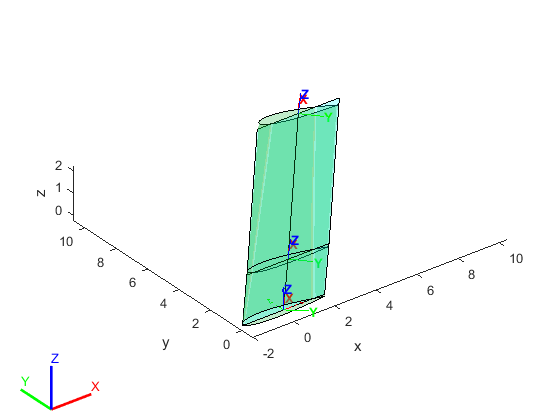

LS.Sweep        = [40, 40];
LS.Sweep_eta    = [0, 1];
LS.Dihedral     = [10, 10];
LS.Dihedral_eta = [0.3, 1];
LS.AoA          = [5, 10];
LS.AoA_eta      = [0.3, 1];
build(LS);
draw(LS);

This example highlights several points:

- The distribution of the different properties along the span does not have to be the same. This is a deliberate choice as aircraft wings often have a different distribution for chord, dihedral, AoA, sweep, etc. so the LiftingSurface object handles these different distributions internally and uses the unique values.

- As the beam axis is assumed to be piecewise linear (an assumption that is inherent to the finite element beams which are used in subsequent analyses) a new coordinate system is automatically generated at any point where the orientation of the beam changes.

- The successive rotation of dihedral and sweep does not twist the wing planform. This is because the sweep, dihedral and AoA are all projected angles. See the LiftingSurface documentation for more details.

- The AoA distribution does not twist the aerodynamic flat plate. This is deliberate as the flat plate geometry defines the aerodynamic panel geometry for thin-aerofoil aerodynamic theories and therefore the edges of the plate must remain parallel with the flow. Note that the cross-sections will be rotated by the angle of attack, hence the green volume can be thought of as the outer mould line of the LiftingSurface.

To demonstrate how generic this parameterisation can be let's try a random distribution of chord values:

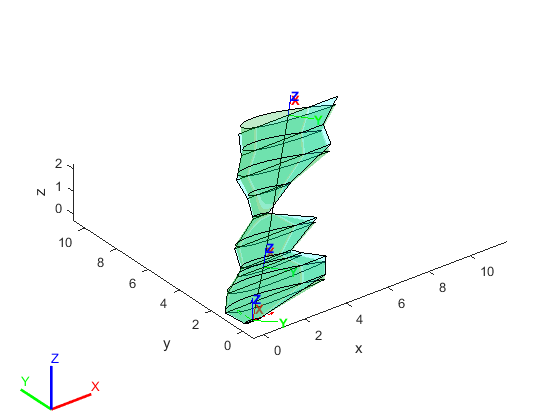

nChord       = 10;
normChord    = rand(1, nChord);
refChord     = 5;
LS.Chord     = refChord .* normChord;
LS.Chord_eta = linspace(0, 1, nChord);

build(LS);
draw(LS);

clear nChord normChord rootChord

**A.2. Defining a lifting surface using the Coordinate Set ('cSet')**

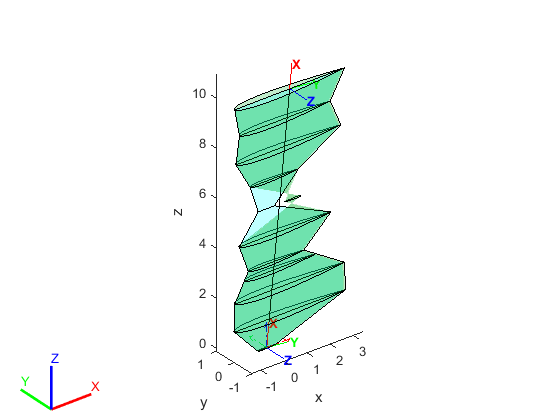

LS.SpanVector = 'Z';
LS.Sweep = [0, 0];
LS.Dihedral = [0,0];
build(LS);    
draw(LS);